# Two-Compartment Model

clc, clearvars, close all
t = linspace(0, 12, 50);
% paramaters
k10 = 0.05;
k12 = 0.1;
k21 = 0.6;
C0 = 10;
% second order system
syms A1(t) A2(t)

ode1 = diff(A1,t) == -k10 * A1 - k12 * A1 + k21 * A2;
ode2 = diff(A2,t) == k12 * A1 - k21 * A2;
odes = [ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}A_{1}\left(t\right)=\frac{3\,A_{2}\left(t\right)}{5}-\frac{3\,A_{1}\left(t\right)}{20}\\ \frac{\partial }{\partial t}A_{2}\left(t\right)=\frac{A_{1}\left(t\right)}{10}-\frac{3\,A_{2}\left(t\right)}{5} \end{array}\right)$$

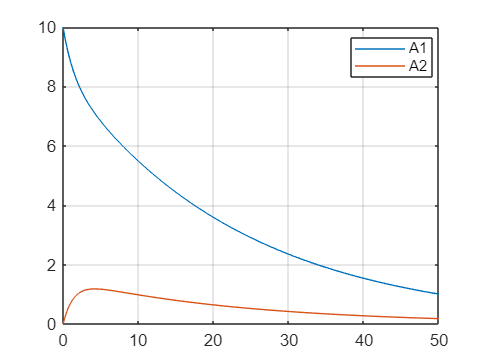


cond1 = A1(0) == C0;
cond2 = A2(0) == 0;
conds = [cond1; cond2];

[A1Sol(t), A2Sol(t)] = dsolve(odes, conds);
fplot(A1Sol,[0 50])
hold on
fplot(A2Sol, [0 50])
grid on
legend("A1","A2", Location = "best")